# Human Activity Recognition Using Signal Feature Extraction and Machine Learning

This example shows how to extract features from smartphone accelerometer signals to classify human activity using a machine learning algorithm. The feature extraction for the data is done using the `signalTimeFeatureExtractor` and `signalFrequencyFeatureExtractor` objects. The features are used to train a support vector machine (SVM) model. 

## **Data Set**

The Sensor HAR (human activity recognition) App [1] was used to collect raw accelerometer signals in [2]. The smartphone was worn by a subject during five different types of physical activity. The data set was then buffered to obtain 44 sample-long signals corresponding to a particular activity. The *Dancing *activity from the data set and the accelerometer signals in the `y` and `z` directions were excluded to create the BufferedHumanActivity data set stored in the `BufferedHumanActivity.mat` file used in this example.

Load the BufferedHumanActivity data set.

load BufferedHumanActivity.mat

The data set contains 7776 x-direction accelerometer signals. Each signal has a duration of 44 samples and corresponds to one of four different physical human activities: *Sitting*, *Standing, Walking* and *Running*. The data set contains the following variables:

- `atx `— Buffered x-direction accelerometer sensor data of fixed length (44 by 7776 matrix)

- `actid` — Response vector containing the activity IDs in integers: 1, 2, 3, and 4 representing *Sitting*, *Standing, Walking* and *Running*, respectively

- actnames — List of activity names for each activity ID

- `fs `—  Sample rate of accelerometer sensor data

## Feature Extraction

The accelerometer signals may be thought of as containing two main components, one consisting of "fast" variations over time caused by body dynamics (physical movements of the subject). The other consisting of "slow" variations over time caused by the position of the body with respect to the vertical gravitational field.

To isolate the rapid signal variations from the slower ones, we apply a high pass filter to the original signals. We extract different features from the filtered and unfiltered signals using the `signalTimeFeatureExtractor` and `signalFrequencyFeatureExtractor` objects. These objects allow performant computation of multiple features in the time and frequency domains with one function call. 

% Filter the signals with a highpass filter
atxFiltered = highpass(atx,0.7,fs);

For time features, two `signalTimeFeatureExtractor` objects are configured. One is used to extract the mean of the unfiltered signals (`meanFE`) and the second is used to extract the root mean square, shape factor, peak value, crest factor, clearance factor, and impulse factor of the filtered signals (`timeFE`).

meanFE = signalTimeFeatureExtractor("Mean",true,"SampleRate",fs);
timeFE = signalTimeFeatureExtractor("RMS",true,...
    "ShapeFactor",true,...
    "PeakValue",true,...
    "CrestFactor",true,...
    "ClearanceFactor",true,...    
    "ImpulseFactor",true,...
    "SampleRate",fs);

For frequency features, `signalFrequencyFeatureExtractor` is used to extract the mean frequency, band power, half-power bandwidth, peak amplitude and peak location of the filtered signals.

freqFE = signalFrequencyFeatureExtractor("PeakAmplitude",true,...
    "PeakLocation",true,...
    "MeanFrequency",true,...
    "BandPower",true,...
    "PowerBandwidth",true,...
    "SampleRate",fs);

The computation of spectral peaks can be refined by setting more parameters. For instance, the maximum number of peaks is set to 6, and the minimum distance between each spectral peak is set to 0.25Hz. Additionally,  we choose an FFT length of 256 and a rectangular window of 44 samples (i.e., the signal length) to compute the spectral estimates. 

fftLength = 256;
window = rectwin(size(atx,1));
setExtractorParameters(freqFE,"WelchPSD","FFTLength",fftLength,"Window",window);
mindist_xunits = 0.25;
minpkdist = floor(mindist_xunits/(fs/fftLength));
setExtractorParameters(freqFE,"PeakAmplitude","MaxNumExtrema",6,"MinSeparation",minpkdist);
setExtractorParameters(freqFE,"PeakLocation","MaxNumExtrema",6,"MinSeparation",minpkdist);

The computation of features for all the signals can be parallelized using transformed array datastores. The datastores read each matrix column and compute features using the `extract` function of the feature extractor objects. 

meanFeatureDs = arrayDatastore(atx,"IterationDimension",2);
meanFeatureDs = transform(meanFeatureDs,@(x)meanFE.extract(x{:}));
timeFeatureDs = arrayDatastore(atxFiltered,"IterationDimension",2);
timeFeatureDs = transform(timeFeatureDs,@(x)timeFE.extract(x{:}));
freqFeatureDs = arrayDatastore(atxFiltered,"IterationDimension",2);
freqFeatureDs = transform(freqFeatureDs,@(x)freqFE.extract(x{:}));

Call the `readall` method of transformed datastore with the "`UseParallel`"  option set to true to distribute the computations across a pool of workers if Parallel Computing Toolbox is installed. The resulting computed features are combined to end up with  22 features for each one of the 7776 signal observations. 

meanFeatures = readall(meanFeatureDs,"UseParallel",true);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


timeFeatures = readall(timeFeatureDs,"UseParallel",true);
freqFeatures = readall(freqFeatureDs,"UseParallel",true);

features = [meanFeatures timeFeatures freqFeatures];

## Train an SVM Classifier Using Extracted Features

You can import the features and activity labels into the Classification Learner app to train an SVM classifier.  Alternatively, you can create an SVM template and classifier using a feature table containing the features (predictors) and the activity labels (response) as follows. 

First create a table with predictors and response. 

featureTable = array2table(features);
actioncats = categorical(actnames)';
featureTable.ActivityID = actioncats(actid);
head(featureTable)

    features1    features2    features3    features4    features5    features6    features7    features8    features9    features10    features11    features12    features13    features14    features15    features16    features17    features18    features19    features20    features21    features22    ActivityID
    _________    _________    _________    _________    _________    _________    _________    _________    _________    __________

Partition the dataset by assigning 75% of the signals for training and 25% for testing. Use the `cvpartition` function to ensure the partitions contain activity labels with similar proportions. 

% Extract predictors and response
predictors = featureTable(:, 1:end-1);
response = featureTable.ActivityID;

% For reproducible results
rng default

% Partition the data and extract training predictors and response data
cvp = cvpartition(response,'Holdout',0.25);
trainingPredictors = predictors(cvp.training, :);
trainingResponse = response(cvp.training, :);

% Train the classifier
template = templateSVM(...
    'KernelFunction', 'polynomial', ...
    'PolynomialOrder', 2, ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 1, ...
    'Standardize', true);
classificationSVM = fitcecoc(...
    trainingPredictors, ...
    trainingResponse, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames',actioncats);

Test the classifier on the test partition and analyze its classification accuracy.

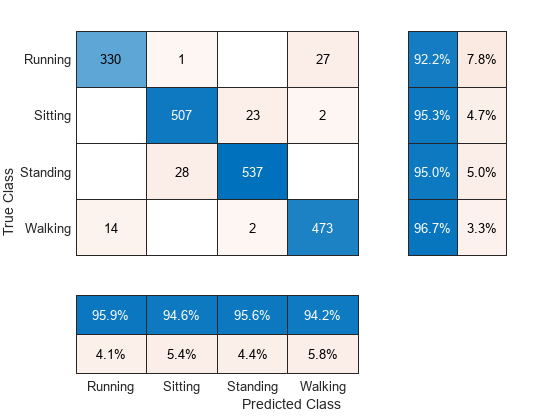

% Extract test predictors and response data
testPredictors = predictors(cvp.test, :);
testResponse = response(cvp.test, :);

% Predict activity on the test data
testPredictions = predict(classificationSVM,testPredictors);

% Plot the confusion matrix to analyze performance of the classifier
figure
cm = confusionchart(testResponse, testPredictions, ...
    ColumnSummary="column-normalized", RowSummary="row-normalized");

accuracy = trace(cm.NormalizedValues)/sum(cm.NormalizedValues, "all");
fprintf("The classification accuracy on the test partition is %2.1f%%", accuracy*100)

The classification accuracy of the classifier on the test partition is 95.0%

Most of the errors occur when misclassifying running as walking and standing as sitting. 

**Summary**

In this example, you saw how to extract features for human activity based on smartphone sensor signals using `signalTimeFeatureExtractor` and `signalFrequencyFeatureExtractor`. You saw how to use the extracted features to train an SVM model which resulted in about 95% accuracy. As an alternative approach, you can also explore using a `featureInput` layer to train a deep learning classifier.

**References**

[1] El Helou, A. Sensor HAR recognition App. MathWorks File Exchange [https://www.mathworks.com/matlabcentral/fileexchange/54138-sensor-har-recognition-app](https://www.mathworks.com/matlabcentral/fileexchange/54138-sensor-har-recognition-app)

[2] El Helou, A. Sensor Data Analytics. MathWorks File Exchange [https://www.mathworks.com/matlabcentral/fileexchange/54139-sensor-data-analytics-french-webinar-code](https://www.mathworks.com/matlabcentral/fileexchange/54139-sensor-data-analytics-french-webinar-code)

*Copyright 2021 The MathWorks, Inc.*